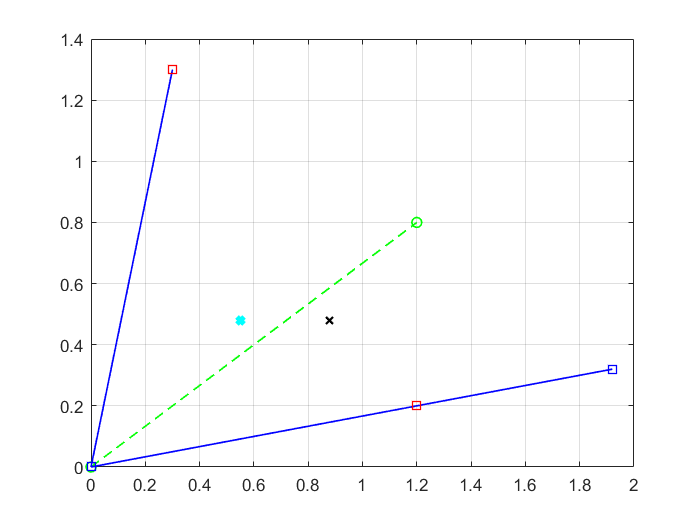

kx = 1.6;
ky = 1;
F = [1.2; 0.8];
K = [1.2 0.3; 0.2 1.3];
Knew = [kx*1.2 ky*0.3; kx*0.2 ky*1.3];
Xnew = inv(K)*F;
Xnewnew = inv(Knew)*F;

plot([0, F(1)], [0, F(2)], 'g--o', 'LineWidth',1); hold on;
plot([0, Knew(1)], [0, Knew(2)], 'b-s', 'LineWidth',1); hold on;
plot([0, Knew(3)], [0, Knew(4)], 'b-s', 'LineWidth',1); hold on;

plot(K(1), K(2), 'r-s', 'LineWidth',1); hold on;
plot(K(3), K(4), 'r-s', 'LineWidth',1); hold on;

plot(Xnew(1), Xnew(2), 'k-x', 'LineWidth',1.35); hold on;
plot(Xnewnew(1), Xnewnew(2), 'c-x', 'LineWidth',3); hold on;

%plot([0, 1], [0, 0], 'r-->', 'LineWidth',1); hold on;
%plot([0, 0], [0, 1], 'b--^', 'LineWidth',1); hold off;
axis on;
grid on;